# Training random forest regression using all data

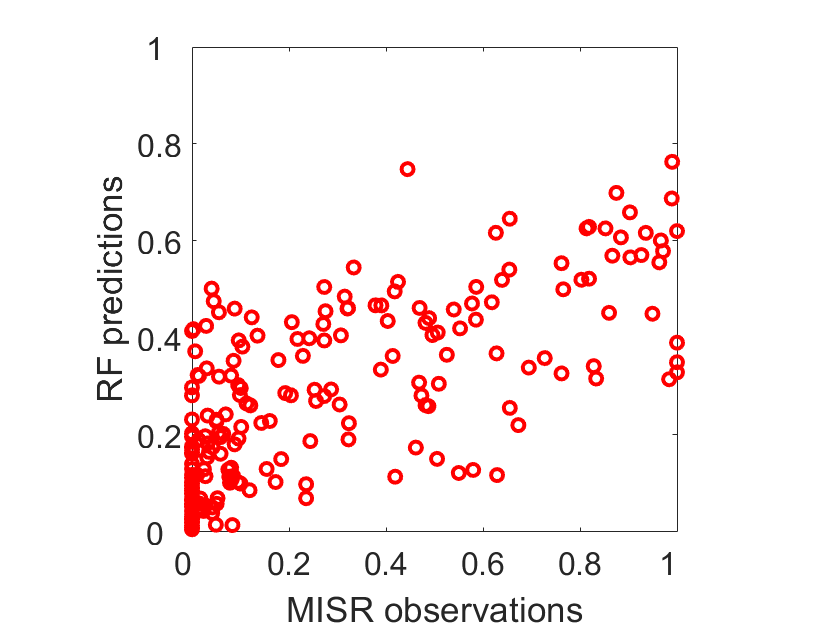

% Input training and testing data
load('C:\Users\fox\Desktop\demo_HEI\random_forest\training_data\predictors.mat');
datanum1 = length(input_1);
load('C:\Users\fox\Desktop\demo_HEI\random_forest\training_data\predictors_201911.mat');
datanum2 = length(input_1);
X        = zeros(datanum1+ datanum2,11);
Y        = zeros(datanum1+ datanum2,1);
load('C:\Users\fox\Desktop\demo_HEI\random_forest\training_data\predictors.mat');
load('C:\Users\fox\Desktop\demo_HEI\random_forest\training_data\totalfrp_summary_2008_2018.mat');
input_12 = totalfrp_summary;
X(1:datanum1,:) = [input_1, input_2, input_3, input_4, input_5, input_6, input_7, input_8, input_10,input_11,input_12];
load('C:\Users\fox\Desktop\demo_HEI\random_forest\training_data\predictors_201911.mat');
load('C:\Users\fox\Desktop\demo_HEI\random_forest\training_data\totalfrp_summary_2019.mat');
input_12 = totalfrp_summary;
X(datanum1+1:datanum1+datanum2,:) = [input_1, input_2, input_3, input_4, input_5, input_6, input_7, input_8, input_10,input_11,input_12];
load('C:\Users\fox\Desktop\demo_HEI\random_forest\training_data\output_variables_ratio.mat');
Y(1:datanum1) = ratio_uppblh_nowind;
load('C:\Users\fox\Desktop\demo_HEI\random_forest\training_data\output_variables_ratio_201911.mat');
Y(datanum1+1:datanum1+datanum2) = ratio_uppblh_nowind;
X_name = {'Landuse','PBLH','T2','RH','U10','V10','RAIN','EMIS','LON','LAT','FRP'};

num_test = 220;
num_record = size(X,1);
index = 1:1:num_record;

index_test = 1:10:2200;
index_train = zeros(num_record - num_test,1);
i = 0;
for ii = 1:num_record
    aa = find(ii == index_test);
    if isempty(aa)
        i = i + 1;
        index_train(i) = ii;
    end
end

input = zeros(num_record-num_test,size(X,2));
input_test = zeros(num_test,size(X,2));
output = zeros(num_record-num_test,1);
output_test = zeros(num_test,1);

for ii = 1:num_test
    input_test(ii,:)  = X(index_test(ii),:);
    output_test(ii,:) = Y(index_test(ii),:);
end

for ii = 1:num_record - num_test
    input(ii,:) = X(index_train(ii),:);
    output(ii,:) = Y(index_train(ii),:);
end

% Training random forest
final_b = TreeBagger(100,input,output,'Method','regression', ...
    'OOBPredictorImportance','On', ...
    'MinLeafSize',5);
predict_output = final_b.predict(input_test);

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
plot(output_test,predict_output,'Marker','o','LineWidth',2,'LineStyle','none','Color',[1 0 0]);
ylabel('RF predictions');
xlabel('MISR observations');
ylim(axes1,[0 1]);
xlim(axes1,[0 1]);
box(axes1,'on');
set(axes1,'FontSize',16);
set(gca,'FontSize',16,'XTick',[0 0.2 0.4 0.6 0.8 1.0],'XTickLabel',[0 0.2 0.4 0.6 0.8 1.0],'YTick',[0 0.2 0.4 0.6 0.8 1.0],'YTickLabel',[0 0.2 0.4 0.6 0.8 1.0]);
axis square

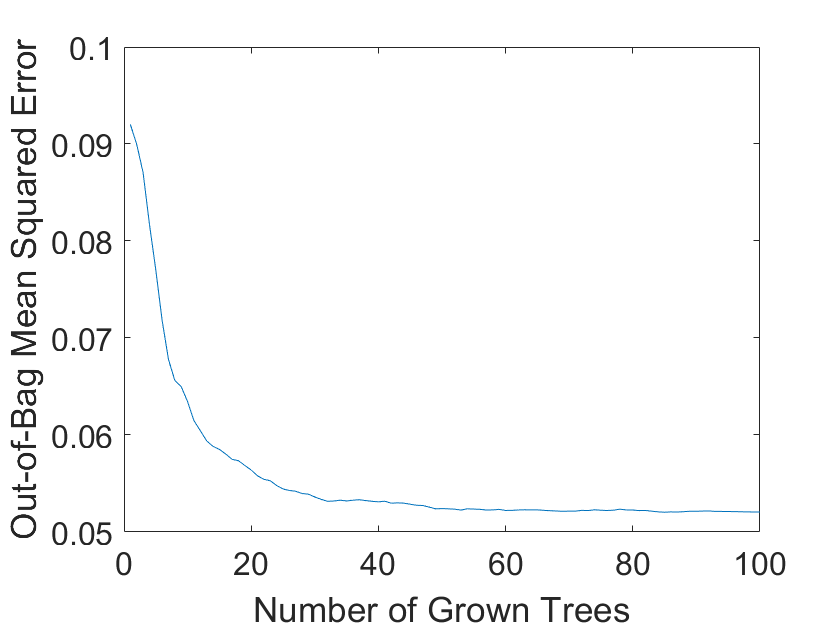


figure2 = figure;
plot(oobError(final_b))
xlabel('Number of Grown Trees')
ylabel('Out-of-Bag Mean Squared Error');
set(gca,'FontSize',16);

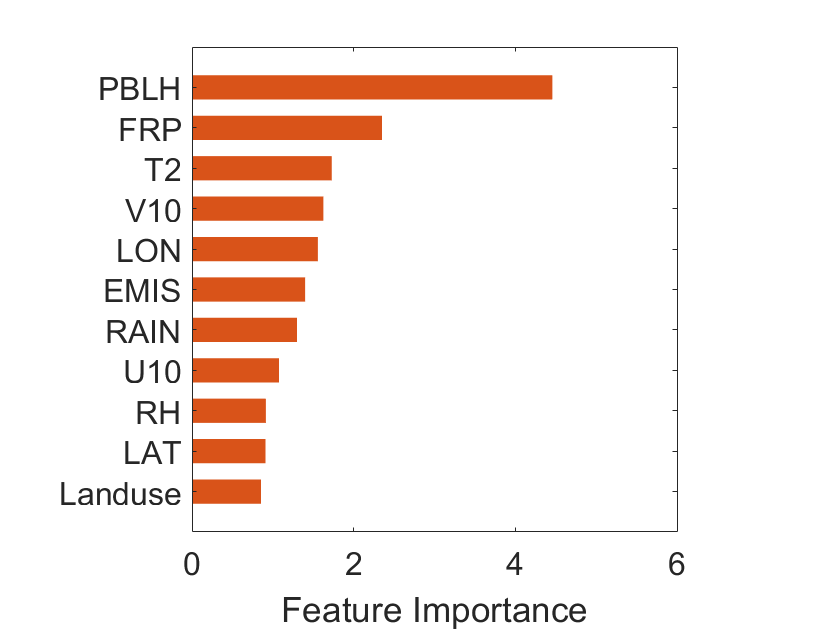


figure3 = figure;
pos1 = [0.3 0.3 0.4 0.4];
aa = final_b.OOBPermutedPredictorDeltaError;
[bb,index] = sort(aa,'ascend');
X_name_new = cell(1,11);
for ii = 1:length(index)
    X_name_new{ii} = X_name{index(ii)};
end

xx = 1:11;
barh(xx,bb,'FaceColor',[0.850980401039124 0.325490206480026 0.0980392172932625],...
    'EdgeColor','none',...
    'BarWidth',0.6);
ylim([0,6]);
ylim([0,12]);
xlabel('Feature Importance');
set(gca,'FontSize',16,'XTick',[0 2 4 6],'XTickLabel',[0 2 4 6],'YTick',[1 2 3 4 5 6 7 8 9 10 11],'YTickLabel',X_name_new);
axis square


mse = mean((predict_output - output_test).^2);
rr  = corrcoef(predict_output,output_test);
r   = rr(1,2);